% Paso 1: Pedir los valores de los puntos
n = input('Número de puntos: '); % Número de puntos

X = zeros(n, 1); % Inicializar vector de X
Y = zeros(n, 1); % Inicializar vector de Y

for i = 1:n
    X(i) = input(['X(' num2str(i) '): ']);
    Y(i) = input(['Y(' num2str(i) '): ']);
end

% Paso 2: Construir la matriz A con una columna adicional de X^2 y el vector Y
A = [ones(n, 1), X, X.^2]; % Matriz A con columna de unos, valores de X, y X^2

% Paso 3: Calcular la fórmula de ajuste
At = A'; % Transpuesta de A
AtA = At * A; % A' * A
AtA_inv = inv(AtA); % Inversa de (A' * A)
AtY = At * Y; % A' * Y
u = AtA_inv * AtY; % Coeficientes de la parábola

% Mostrar los resultados
disp('Coeficientes de la ecuación cuadrática:');

Coeficientes de la ecuación cuadrática:


disp(['Intercepto (a): ' num2str(u(1))]);

Intercepto (a): 3.75


disp(['Coeficiente lineal (b): ' num2str(u(2))]);

Coeficiente lineal (b): -0.81061


disp(['Coeficiente cuadrático (c): ' num2str(u(3))]);

Coeficiente cuadrático (c): -0.037879



% Evaluar Y_hat para el modelo cuadrático
Y_hat_cuadratica = u(1) + u(2) * X + u(3) * X.^2;

% ---------- CÁLCULO DEL ERROR CUADRÁTICO MEDIO (ECM) ----------

% ECM para el modelo cuadrático
ECM_cuadratica = sum((Y - Y_hat_cuadratica).^2) / n;

% Mostrar el error cuadrático medio
disp(['Error Cuadrático Medio (ECM) - Modelo Cuadrático: ' num2str(ECM_cuadratica)]);

Error Cuadrático Medio (ECM) - Modelo Cuadrático: 1.5928


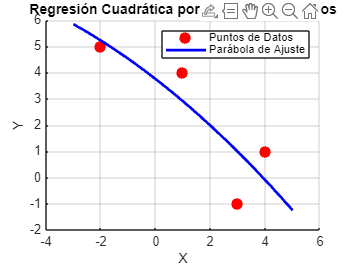


% ---------- GRAFICAR LOS RESULTADOS ----------

% Crear la gráfica
figure;
hold on;
grid on;

% Graficar los puntos de datos
plot(X, Y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'DisplayName', 'Puntos de Datos');

% Graficar la parábola de ajuste
x_vals = linspace(min(X) - 1, max(X) + 1, 100); % Intervalo de la gráfica
y_vals = u(1) + u(2) * x_vals + u(3) * x_vals.^2; % Valores de Y para la parábola de ajuste
plot(x_vals, y_vals, 'b-', 'LineWidth', 2, 'DisplayName', 'Parábola de Ajuste');

% Añadir etiquetas y título
xlabel('X');
ylabel('Y');
title('Regresión Cuadrática por Mínimos Cuadrados');
legend('show');